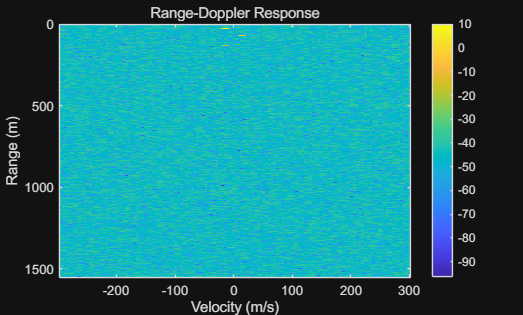

% OFDM-based Radar System Implementation
% This script implements an OFDM-based radar system with the following features:
% - Configurable system parameters (carrier frequency, bandwidth, etc.)
% - 16-QAM modulation
% - Cyclic prefix for handling multipath
% - Range-Doppler processing

%% System Configuration
% Basic radar parameters
radar.fc = 24e9;          % Carrier frequency (24 GHz)
radar.B = 100e6;          % Bandwidth (100 MHz)
radar.fs = radar.B;       % Sampling frequency equals bandwidth

% OFDM parameters
ofdm.Nsc = 1024;         % Number of subcarriers
ofdm.df = radar.B/ofdm.Nsc;  % Subcarrier spacing
ofdm.Tsym = 1/ofdm.df;   % OFDM symbol duration
ofdm.Ncp = 16;           % Cyclic prefix length
ofdm.Tcp = ofdm.Ncp/radar.fs;  % CP duration
ofdm.Tofdm = ofdm.Tsym + ofdm.Tcp;  % Total OFDM symbol duration
ofdm.Nofdm = ofdm.Nsc + ofdm.Ncp;   % Samples per OFDM symbol
ofdm.M = 128;            % Number of OFDM symbols to transmit

% Modulation parameters
mod.bps = 4;             % Bits per symbol (16-QAM)
mod.K = 2^mod.bps;       % Modulation order

%% Signal Generation
% Generate random binary data
dataTx = randi([0,1], [ofdm.Nsc*mod.bps ofdm.M]);

% QAM modulation
qamTx = qammod(dataTx, mod.K, 'InputType', 'bit', 'UnitAveragePower', true);

% OFDM modulation
ofdmTx = ofdmmod(qamTx, ofdm.Nsc, ofdm.Ncp);

% Reshape into matrix (each column is one OFDM symbol)
xofdm = reshape(ofdmTx, ofdm.Nofdm, ofdm.M);

%% Signal Reception and Processing
% Receive signal after target reflection
yofdmr = receiveSignal_multiTarget(xofdm, radar.fs, radar.fc, ofdm.Tofdm);

% Reshape and demodulate
yofdmr1 = reshape(yofdmr, ofdm.Nofdm*ofdm.M, 1);
Yofdmr = ofdmdemod(yofdmr1, ofdm.Nsc, ofdm.Ncp);

% Calculate channel response
Zofdmr = Yofdmr./qamTx;

%% Range-Doppler Processing
% Configure Range-Doppler Response object
rdr = phased.RangeDopplerResponse('RangeMethod', 'FFT', ...
    'SampleRate', radar.fs, ...
    'SweepSlope', -radar.B/ofdm.Tofdm, ...
    'RangeWindow', 'Hamming', ...
    'DopplerWindow', 'Hamming', ...
    'DopplerOutput', 'Speed', ...
    'OperatingFrequency', radar.fc, ...
    'PRFSource', 'Property', ...
    'PRF', 1/ofdm.Tofdm, ...
    'ReferenceRangeCentered', false);

% Generate Range-Doppler map
[resp, rngGrid, dopGrid] = step(rdr, Zofdmr);
rdResponse = abs(resp);

%% Visualization
% 2D Range-Doppler map
figure('Name', 'Range-Doppler Map');
imagesc(dopGrid, rngGrid, mag2db(rdResponse));
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Range-Doppler Response');
colorbar;

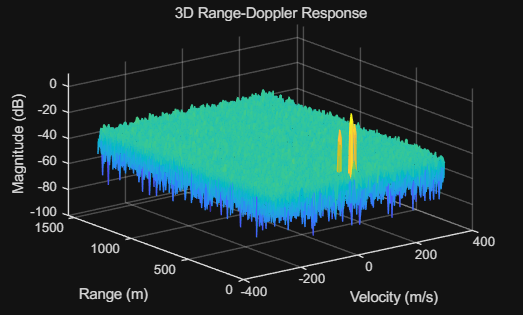


% 3D mesh plot
figure('Name', '3D Range-Doppler Response');
[XF, YF] = meshgrid(dopGrid, rngGrid);
mesh(XF, YF, mag2db(rdResponse));
xlabel('Velocity (m/s)');
ylabel('Range (m)');
zlabel('Magnitude (dB)');
title('3D Range-Doppler Response');

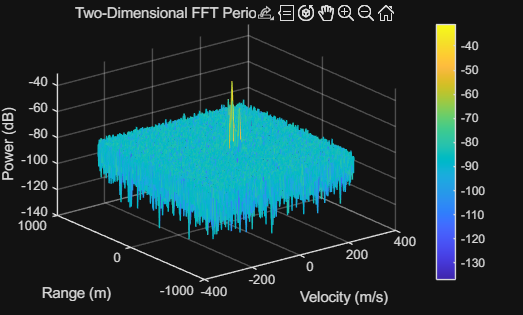

%% Two-Dimensional FFT Periodogram-based Estimation Algorithm
% This implementation follows the mathematical definition:
% PerF(n,l) = (1/NM)|sum_k(sum_m(F_m,k * exp(-j2π*ml/M) * exp(j2π*kn/N))|^2

% Define FFT sizes for higher resolution
M_FFT = ofdm.M;   % Doppler FFT size
N_FFT = ofdm.Nsc;  % Range FFT size

% Get the channel frequency response matrix F
F = Zofdmr;

% Zero-padding for improved resolution
F_padded = zeros(N_FFT, M_FFT);
F_padded(1:size(F,1), 1:size(F,2)) = F;

% Step 1: Perform M-point FFT (Doppler processing)
% The inner sum in the equation corresponds to Doppler processing
% exp(-j2π*ml/M) term is implemented by the FFT
doppler_fft = zeros(size(F_padded));
for k = 1:N_FFT
    doppler_fft(k,:) = fftshift(fft(F_padded(k,:), M_FFT));
end

% Step 2: Perform N-point FFT (Range processing)
% The outer sum in the equation corresponds to range processing
% exp(j2π*kn/N) term is implemented by the FFT
range_doppler_fft = zeros(size(doppler_fft));
for l = 1:M_FFT
    range_doppler_fft(:,l) = fftshift(fft(doppler_fft(:,l), N_FFT));
end

% Step 3: Calculate periodogram with proper normalization
% The 1/NM factor ensures proper power scaling
Per_F = (1/(N_FFT * M_FFT)) * abs(range_doppler_fft).^2;

%% Calculate Physical Parameters
% Range axis calculation
c = 3e8;  % Speed of light
range_res = c/(2*radar.B);  % Range resolution (c/2B)
range_axis = (-N_FFT/2:N_FFT/2-1) * range_res;

% Velocity axis calculation
lambda = c/radar.fc;  % Wavelength
velocity_res = lambda/(2*ofdm.M*ofdm.Tofdm);  % Velocity resolution
velocity_axis = (-M_FFT/2:M_FFT/2-1) * velocity_res;

%% Visualization of Results
% Create 3D mesh plot with proper physical units
[V, R] = meshgrid(velocity_axis, range_axis);

% Convert to dB scale for better visualization
Per_F_dB = 10*log10(Per_F + eps);  % Add eps to avoid log(0)

% 3D Mesh Plot
figure('Name', 'Periodogram-based Range-Doppler Estimation');
mesh(V, R, Per_F_dB);
xlabel('Velocity (m/s)');
ylabel('Range (m)');
zlabel('Power (dB)');
title('Two-Dimensional FFT Periodogram Estimation');
colorbar;
grid on;

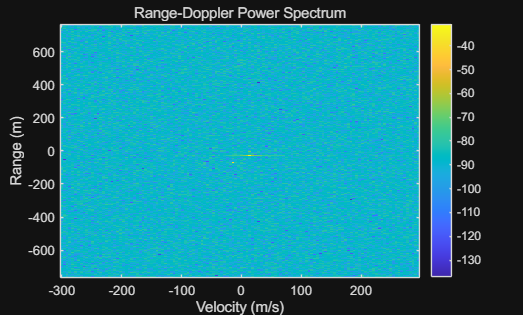


% 2D Intensity Plot
figure('Name', 'Range-Doppler Map');
imagesc(velocity_axis, range_axis, Per_F_dB);
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Range-Doppler Power Spectrum');
colorbar;
axis xy;


%% Peak Detection and Target Parameters
% Find local maxima above a threshold
threshold_dB = max(Per_F_dB(:)) - 15;  % 15 dB below maximum
[peaks_r, peaks_v] = find(Per_F_dB > threshold_dB);

% Convert peak indices to physical parameters
detected_ranges = range_axis(peaks_r);
detected_velocities = velocity_axis(peaks_v);

% Display detected targets
disp('Detected Targets:');

Detected Targets:


for i = 1:length(peaks_r)
    fprintf('Target %d: Range = %.2f m, Velocity = %.2f m/s\n', ...
            i, detected_ranges(i), detected_velocities(i));
end

Target 1: Range = -70.50 m, Velocity = -14.09 m/s
Target 2: Range = -30.00 m, Velocity = 14.09 m/s
Target 3: Range = -28.50 m, Velocity = 14.09 m/s
